Initiate

close all
clearvars
clc
if ~exist('../Figures', 'dir')
    mkdir('../Figures')
end
cd ../results/

Load data files

load('dxyz.dat',             '-ascii');
load('Nxyz.dat',             '-ascii');
rho.data = load('rhoAmb.dat','-ascii');
gnd.alt  = load('z_gnd.dat', '-ascii');

Derive main parameters

N.x = Nxyz(1);
N.y = Nxyz(2);
N.z = Nxyz(3);

d.x = dxyz(1);           % _m
d.y = dxyz(2);           % _m
d.z = dxyz(3);           % _m

L.x = (N.x-1)*d.x;         % _m
L.y = (N.y-1)*d.y;         % _m
L.z = (N.z-1)*d.z;         % _m

rho.data = ConvertTo3d(rho.data,Nxyz); % _C/_m^3

clear Nxyz
clear dxyz
clear InitPoint
cd ../viz

x = ((0:(N.x-1))*d.x)*1e-3;
y = ((0:(N.y-1))*d.y)*1e-3;
z = ((0:(N.z-1))*d.z + gnd.alt)*1e-3;

[X,Y,Z] = meshgrid(x,y,z);
rho.max = max(max(max(rho.data)));
rho.min = min(min(min(rho.data)));

Map ColorScale

gnd.color = [.75 .75 .75]; % light gray for neutral charges

Draw the tree

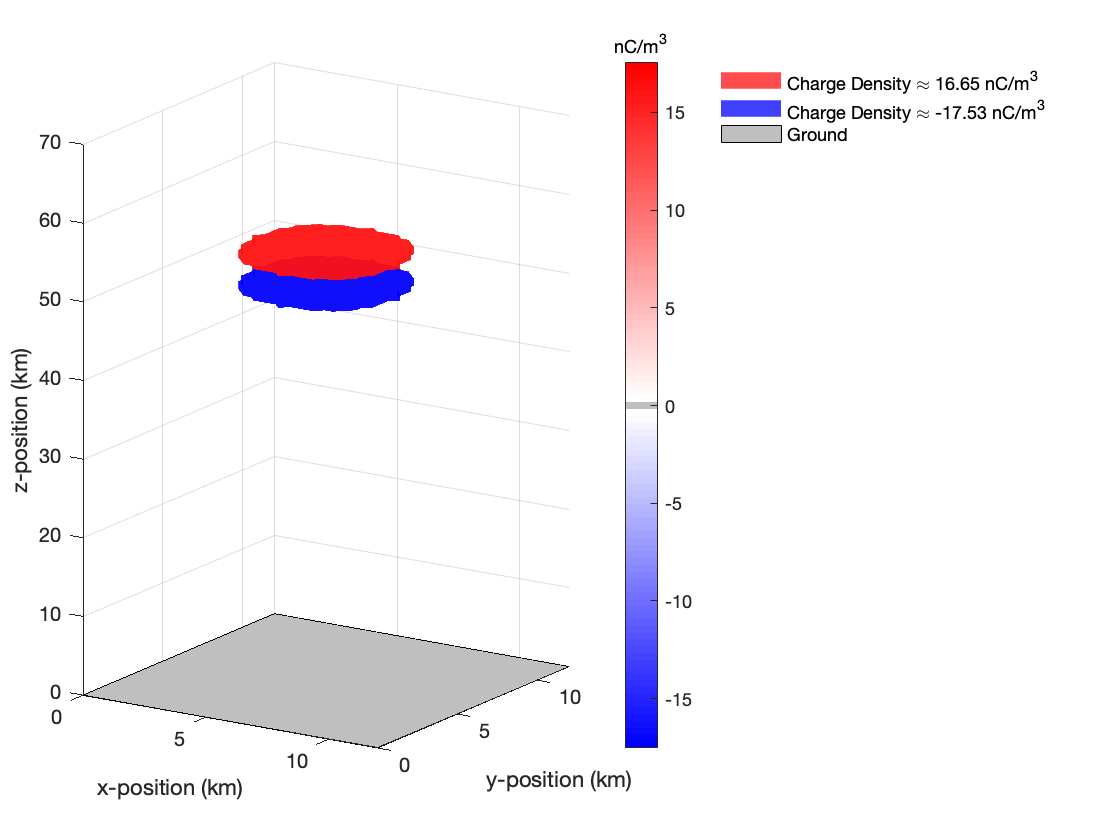

figure(1);
hold on;
% Sets bounds for the axes (comment out if clouds get cut off):
%axis([L.x*1/5 L.x*4/5 L.y*1/5 L.y*4/5 gnd.alt 2/2*(L.z+gnd.alt)]*1e-3) % Slight crop
axis([0 L.x 0 L.y gnd.alt 2/2*(L.z+gnd.alt)]*1e-3)                     % Full span 

% Calls the new function that automatically recognizes charge regions:
plottingChargeRegions('white',0.03,rho,X,Y,Z,x,y,z);
% Represents the neutrally charged (grounded) surface:
P.x = [L.x 0 0 L.x]*1e-3;
P.y = [L.y L.y 0 0]*1e-3;
P.z = [gnd.alt gnd.alt gnd.alt gnd.alt]*1e-3;
patch(P.x, P.y, P.z, gnd.alt,'FaceColor',gnd.color,'DisplayName','Ground');

% view([90,0]) 
% camlight; lighting gouraud


function [AA] = ConvertTo3d(A,B)
    [M, N] = size(A);
    AA = zeros(B');
    for m=1:M
        for n=1:N
            ii = rem(m,B(1));
            if(ii==0)
                ii = B(1);
            end
            jj = n;
            kk = (m-ii)/B(1)+1;
            AA(ii,jj,kk) = A(m,n);
        end
    end
end